clear;

sGes = load("sGes.mat")

sGes = struct with fields:
    sGes: [565248×3 double]



hGes = load("hGes.mat")

hGes = struct with fields:
    hGes: [1×1 struct]


t=[-3, 0, 5]; f_borders=[4, 30]; t_ref = [-2.5, -0.5];

addpath("ERDS-Maps")

map1 = calcErdsMap(sGes.sGes, hGes.hGes, t, f_borders,'class', 1,'ref',t_ref,'sig','boot','alpha',0.01,'montage',[1 1 1]);

map2 = calcErdsMap(sGes.sGes, hGes.hGes, t, f_borders,'class', 2,'ref',t_ref,'sig','boot','alpha',0.01,'montage',[1 1 1]);

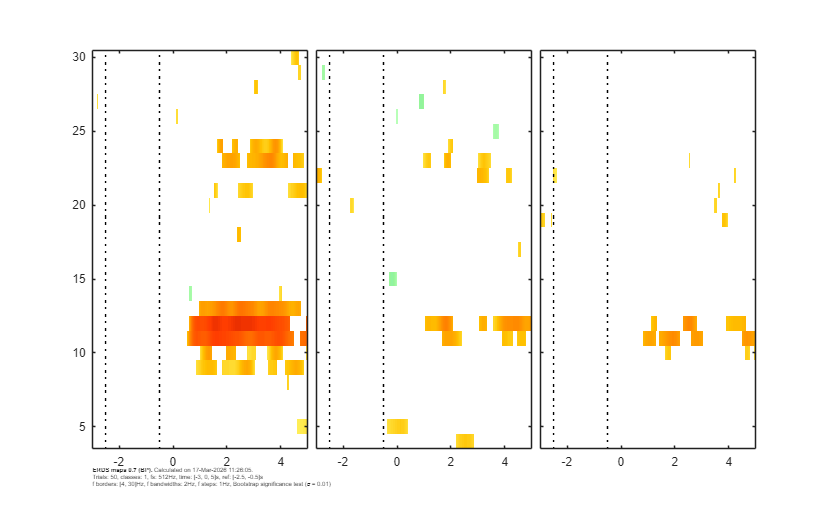


plotErdsMap(map1)

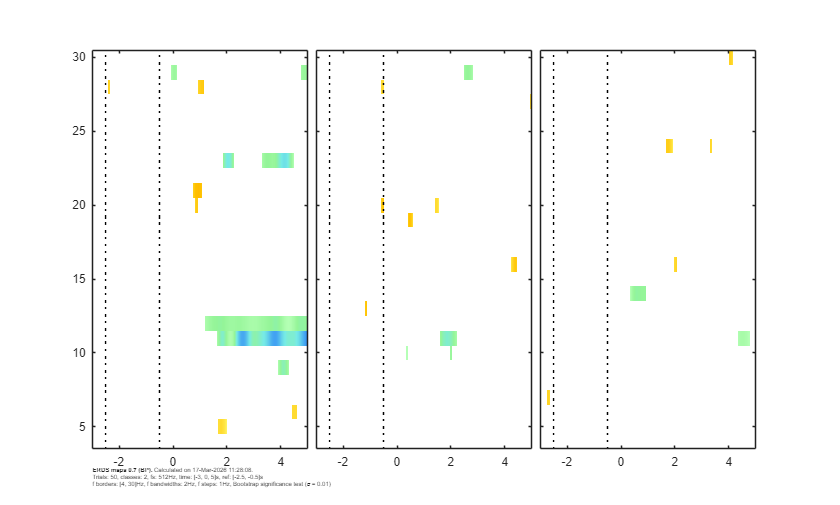

plotErdsMap(map2)

fs = 512

fs = 512

window_size = fs * 2

window_size = 1024


onset = hGes.hGes.TRIG

onset =         6657       12083       17532       22969       28573       34200       39697       45186       50721       56006       61198       66738       72334       77886       83027       88445       93820       99181      104539      109889      120321      125820      131255      136528      142040      147507      153000      158441      163988      169446      175058      180522      185971      191371      196897      202529      207782      213242      218541      223850      234497      240034      245205      250559      255975      261510      266838      271988      277356      282669



window_interest = zeros(length(onset), window_size, 3)

window_interest = window_interest(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

window_reference = zeros(length(onset), window_size, 3)

window_reference = window_reference(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i=1:length(onset)
    start_idx = onset(i)
    end_idx = start_idx + window_size -1
    end_idx_ref = start_idx - window_size +1
    window_interest(i, :, :) = sGes.sGes(start_idx+fs:end_idx+fs, :)
    window_reference(i, :, :) = sGes.sGes(end_idx_ref:start_idx, :)
end

start_idx = 6657

end_idx = 7680

end_idx_ref = 5634

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 12083

end_idx = 13106

end_idx_ref = 11060

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 17532

end_idx = 18555

end_idx_ref = 16509

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 22969

end_idx = 23992

end_idx_ref = 21946

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 28573

end_idx = 29596

end_idx_ref = 27550

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 34200

end_idx = 35223

end_idx_ref = 33177

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 39697

end_idx = 40720

end_idx_ref = 38674

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 45186

end_idx = 46209

end_idx_ref = 44163

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 50721

end_idx = 51744

end_idx_ref = 49698

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 56006

end_idx = 57029

end_idx_ref = 54983

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 61198

end_idx = 62221

end_idx_ref = 60175

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 66738

end_idx = 67761

end_idx_ref = 65715

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 72334

end_idx = 73357

end_idx_ref = 71311

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 77886

end_idx = 78909

end_idx_ref = 76863

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 83027

end_idx = 84050

end_idx_ref = 82004

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 88445

end_idx = 89468

end_idx_ref = 87422

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 93820

end_idx = 94843

end_idx_ref = 92797

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 99181

end_idx = 100204

end_idx_ref = 98158

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 104539

end_idx = 105562

end_idx_ref = 103516

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 109889

end_idx = 110912

end_idx_ref = 108866

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 120321

end_idx = 121344

end_idx_ref = 119298

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 125820

end_idx = 126843

end_idx_ref = 124797

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 131255

end_idx = 132278

end_idx_ref = 130232

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 136528

end_idx = 137551

end_idx_ref = 135505

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 142040

end_idx = 143063

end_idx_ref = 141017

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 147507

end_idx = 148530

end_idx_ref = 146484

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 153000

end_idx = 154023

end_idx_ref = 151977

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 158441

end_idx = 159464

end_idx_ref = 157418

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 163988

end_idx = 165011

end_idx_ref = 162965

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 169446

end_idx = 170469

end_idx_ref = 168423

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 175058

end_idx = 176081

end_idx_ref = 174035

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 180522

end_idx = 181545

end_idx_ref = 179499

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 185971

end_idx = 186994

end_idx_ref = 184948

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 191371

end_idx = 192394

end_idx_ref = 190348

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 196897

end_idx = 197920

end_idx_ref = 195874

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 202529

end_idx = 203552

end_idx_ref = 201506

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 207782

end_idx = 208805

end_idx_ref = 206759

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 213242

end_idx = 214265

end_idx_ref = 212219

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 218541

end_idx = 219564

end_idx_ref = 217518

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 223850

end_idx = 224873

end_idx_ref = 222827

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 234497

end_idx = 235520

end_idx_ref = 233474

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 240034

end_idx = 241057

end_idx_ref = 239011

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 245205

end_idx = 246228

end_idx_ref = 244182

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 250559

end_idx = 251582

end_idx_ref = 249536

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 255975

end_idx = 256998

end_idx_ref = 254952

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 261510

end_idx = 262533

end_idx_ref = 260487

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 266838

end_idx = 267861

end_idx_ref = 265815

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 271988

end_idx = 273011

end_idx_ref = 270965

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 277356

end_idx = 278379

end_idx_ref = 276333

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 282669

end_idx = 283692

end_idx_ref = 281646

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 288151

end_idx = 289174

end_idx_ref = 287128

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 293563

end_idx = 294586

end_idx_ref = 292540

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 298917

end_idx = 299940

end_idx_ref = 297894

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 304403

end_idx = 305426

end_idx_ref = 303380

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 309570

end_idx = 310593

end_idx_ref = 308547

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 314929

end_idx = 315952

end_idx_ref = 313906

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 320052

end_idx = 321075

end_idx_ref = 319029

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 325259

end_idx = 326282

end_idx_ref = 324236

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 330545

end_idx = 331568

end_idx_ref = 329522

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 335781

end_idx = 336804

end_idx_ref = 334758

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 346625

end_idx = 347648

end_idx_ref = 345602

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 351977

end_idx = 353000

end_idx_ref = 350954

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 357419

end_idx = 358442

end_idx_ref = 356396

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 362905

end_idx = 363928

end_idx_ref = 361882

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 368239

end_idx = 369262

end_idx_ref = 367216

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 373664

end_idx = 374687

end_idx_ref = 372641

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 378985

end_idx = 380008

end_idx_ref = 377962

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 384544

end_idx = 385567

end_idx_ref = 383521

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 389675

end_idx = 390698

end_idx_ref = 388652

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 394884

end_idx = 395907

end_idx_ref = 393861

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 400142

end_idx = 401165

end_idx_ref = 399119

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 405593

end_idx = 406616

end_idx_ref = 404570

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 411026

end_idx = 412049

end_idx_ref = 410003

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 416652

end_idx = 417675

end_idx_ref = 415629

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 422214

end_idx = 423237

end_idx_ref = 421191

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 427445

end_idx = 428468

end_idx_ref = 426422

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 432585

end_idx = 433608

end_idx_ref = 431562

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 437838

end_idx = 438861

end_idx_ref = 436815

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 442983

end_idx = 444006

end_idx_ref = 441960

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 448524

end_idx = 449547

end_idx_ref = 447501

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 459265

end_idx = 460288

end_idx_ref = 458242

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 464530

end_idx = 465553

end_idx_ref = 463507

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 469985

end_idx = 471008

end_idx_ref = 468962

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 475173

end_idx = 476196

end_idx_ref = 474150

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 480587

end_idx = 481610

end_idx_ref = 479564

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 486093

end_idx = 487116

end_idx_ref = 485070

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 491473

end_idx = 492496

end_idx_ref = 490450

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 496801

end_idx = 497824

end_idx_ref = 495778

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 502387

end_idx = 503410

end_idx_ref = 501364

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 507718

end_idx = 508741

end_idx_ref = 506695

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 513214

end_idx = 514237

end_idx_ref = 512191

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 518606

end_idx = 519629

end_idx_ref = 517583

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 523809

end_idx = 524832

end_idx_ref = 522786

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 529087

end_idx = 530110

end_idx_ref = 528064

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 534650

end_idx = 535673

end_idx_ref = 533627

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 539928

end_idx = 540951

end_idx_ref = 538905

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 545131

end_idx = 546154

end_idx_ref = 544108

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 550519

end_idx = 551542

end_idx_ref = 549496

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 556025

end_idx = 557048

end_idx_ref = 555002

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

start_idx = 561193

end_idx = 562216

end_idx_ref = 560170

window_interest = window_interest(:,:,1) =

   -4.6120   -1.7098    0.9735    0.3536    5.6538    8.0436    6.0013   -2.9325   -6.0376    1.4751   -1.7963   -1.3240    5.2412   -1.9227   -4.0324    6.0270    7.5898    1.5254   -1.3223    0.8875    7.1330    8.0672    4.0790    5.1694    1.9391   -4.9713   -5.4902   -2.7302    4.4368    3.8878   -2.2373    1.8805    3.4192    3.7588    2.5293   -2.3677    1.1263   -2.7744   -3.0224    8.9861    2.7003   -2.0115    6.2281    3.2176    2.6307    3.1774   -2.1922    2.7471    2.8239   -3.4511    0.3046    3.3385    0.6613   -1.7694   -0.7365    0.8763    0.5448    0.4085    1.8867    2.8851    0.0830   -1.3318   -0.8735    0.2749    1.4442   -1.7574   -0.3978    2.6496   -1.2035   -1.0757    2.1765    1.6383    1.8557    1.6447   -0.5380   -1.1331   -0.9925    0.1045    0.1300   -1.0754    0.0478    1.1133    2.2858    1.9932   -0.7979   -1.7827   -1.7267   -1.8607   -0.6135    0.7886    0.3714   -0.2577    0.1809    0.2458   -0.2938    0.

window_reference = window_reference(:,:,1) =

   -0.5073   -0.0376   -0.6841    0.4536    1.3798    1.0856   -0.1068    0.4322    1.8676    0.4272    1.6530    3.0075   -1.3088   -2.1774    1.5132    1.4550    1.0759    1.9886   -0.3390   -0.1815    1.1011   -1.8127   -1.8644   -1.1443   -1.5730   -0.2035   -1.0558   -0.6706    0.4910   -1.1930   -0.7584    0.2798   -0.7992   -1.8799   -0.2747    1.0055   -3.1590   -3.3242    0.8889   -0.4966   -0.7795    0.6003   -0.3722   -0.2689   -1.5275   -1.6806   -0.7361   -1.6429   -0.8568   -1.0781    0.2426    1.4954   -0.4609    1.8004    1.3701   -1.5701   -0.2135   -0.8614   -2.6298   -1.4042    0.9835    0.1459   -1.2671   -0.3925   -0.8114   -0.4773   -0.1975   -1.0948   -2.0826   -3.2335   -0.3964    1.2449   -2.0840   -2.3619    0.5298    1.3576   -1.0528   -1.5771    0.7755   -1.1201   -0.6977    2.4436   -1.0480   -1.0184    1.2635   -1.3556   -0.8493   -0.0322   -0.8581   -0.4989   -0.6155   -1.0428   -1.9389   -2.8011   -2.2639   -

labels = hGes.hGes.Classlabel

labels =      1     1     1     2     2     1     1     2     2     2     1     1     2     2     2     2     1     2     1     1     1     1     2     2     2     2     1     2     1     1     2     1     1     2     1     2     1     2     2     1     2     2     1     1     1     2     1     2     1     2


labels = labels == 1

labels = 1×100 logical array
   1   1   1   0   0   1   1   0   0   0   1   1   0   0   0   0   1   0   1   1   1   1   0   0   0   0   1   0   1   1   0   1   1   0   1   0   1   0   0   1   0   0   1   1   1   0   1   0   1   0


hand = window_interest(labels)

hand =    -4.6120   -1.2319    0.4745   -0.1314    0.4366   -1.4253   -0.2172    0.8963    0.5588   -3.4185    5.3528   -1.6598   -0.7456    2.4293    0.7890   -0.7043    1.5223   -1.6768    0.2254   -1.1941   -0.9228    1.3307    0.5218    1.1086   -1.4079   -1.6137    0.7802    1.4751    0.7962   -2.1175   -0.4528    0.4759    0.3603   -0.6723   -1.8907   -0.8263   -1.1444   -1.0203    0.2545    1.0603    2.7856    0.0681    1.9234   -0.5737    1.1514    1.5790   -1.5129   -2.6962    2.9045    2.6128


feet = window_interest(~labels)

feet =     1.9238    3.4477   -2.6615    0.5531   -0.1150    1.3805   -0.2279    2.7210    2.7117   -1.3203    0.2932   -1.5605   -1.8192    1.7004    0.7510    1.4478   -0.6319   -0.8568   -2.9862   -0.7816    0.3811   -0.2165    0.0034    0.9430   -1.4138    1.3003    1.1840    2.3139    1.8745    0.2723   -1.8243   -0.3954   -1.2851    1.6496    0.5374   -1.4030    1.3852   -1.4195   -1.8360    1.0133   -3.2859   -1.5912   -1.5963    1.8267    0.3505    1.5092    0.2059    0.9331   -1.2805    2.8020


lowCutoff = 8 % Low cutoff frequency

lowCutoff = 8

highCutoff = 13; % High cutoff frequency
[b, a] = butter(4, [lowCutoff, highCutoff] / (fs / 2), 'bandpass');

% Apply the bandpass filter to the data
filteredHand = filtfilt(b, a, hand);
filteredFeet = filtfilt(b, a, feet);
filteredreference = filtfilt(b, a, window_reference);

filteredHand = filteredHand .^ 2

filteredHand =     0.0000    0.0022    0.0086    0.0181    0.0295    0.0414    0.0525    0.0620    0.0690    0.0730    0.0739    0.0717    0.0669    0.0598    0.0513    0.0421    0.0327    0.0239    0.0161    0.0098    0.0050    0.0019    0.0003    0.0000    0.0008    0.0022    0.0039    0.0058    0.0074    0.0087    0.0094    0.0097    0.0095    0.0088    0.0078    0.0066    0.0054    0.0041    0.0030    0.0020    0.0012    0.0007    0.0003    0.0001    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003


filteredFeet = filteredFeet .^ 2

filteredFeet =     0.0010    0.0014    0.0018    0.0021    0.0024    0.0026    0.0027    0.0027    0.0026    0.0024    0.0021    0.0018    0.0014    0.0011    0.0008    0.0005    0.0003    0.0001    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005    0.0004    0.0004    0.0003    0.0002    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


filteredreference = filteredreference .^ 2

filteredreference = filteredreference(:,:,1) =

    0.0002    0.0047    0.0113    0.0079    0.0045    0.0050    0.0000    0.0001    0.0007    0.0000    0.0001    0.0004    0.0014    0.0000    0.0010    0.0068    0.0008    0.0001    0.0049    0.0054    0.0063    0.0024    0.0035    0.0001    0.0016    0.0010    0.0013    0.0041    0.0163    0.0097    0.0081    0.0166    0.0129    0.0046    0.0084    0.0059    0.0015    0.0167    0.0099    0.0002    0.0041    0.0000    0.0017    0.0000    0.0021    0.0033    0.0032    0.0247    0.0102    0.0024    0.0013    0.0036    0.0002    0.0044    0.0084    0.0001    0.0001    0.0020    0.0001    0.0007    0.0014    0.0176    0.0000    0.0000    0.0060    0.0000    0.0014    0.0140    0.0055    0.0008    0.0046    0.0024    0.0000    0.0012    0.0072    0.0143    0.0015    0.0004    0.0000    0.0014    0.0042    0.0000    0.0001    0.0006    0.0039    0.0055    0.0109    0.0001    0.0008    0.0124    0.0114    0.0002    0.0012    0.0015    0.0001  


filteredHand = log(filteredHand)

filteredHand =   -11.7322   -6.1313   -4.7565   -4.0105   -3.5242   -3.1856   -2.9461   -2.7803   -2.6734   -2.6168   -2.6049   -2.6348   -2.7050   -2.8160   -2.9693   -3.1687   -3.4202   -3.7338   -4.1259   -4.6252   -5.2884   -6.2520   -8.0262  -10.2729   -7.1834   -6.1322   -5.5359   -5.1550   -4.9055   -4.7482   -4.6622   -4.6354   -4.6605   -4.7334   -4.8523   -5.0173   -5.2303   -5.4954   -5.8197   -6.2148   -6.7005   -7.3127   -8.1260   -9.3407  -12.0021  -11.3721   -9.6084   -8.8575   -8.4492   -8.2246


filteredFeet = log(filteredFeet)

filteredFeet =    -6.9480   -6.6000   -6.3464   -6.1632   -6.0367   -5.9582   -5.9226   -5.9266   -5.9689   -6.0492   -6.1689   -6.3308   -6.5395   -6.8027   -7.1327   -7.5501   -8.0924   -8.8389  -10.0077  -12.8589  -11.5163   -9.7824   -8.9515   -8.4385   -8.0959   -7.8641   -7.7131   -7.6260   -7.5930   -7.6081   -7.6676   -7.7703   -7.9160   -8.1067   -8.3458   -8.6395   -8.9979   -9.4372   -9.9865  -10.7025  -11.7218  -13.5555  -15.8553  -12.8354  -11.8526  -11.3278  -11.0218  -10.8508  -10.7756  -10.7754


filteredreference = log(filteredreference);

Y_hand = -1*ones(size(filteredHand))

Y_hand =     -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1


Y_feet = ones(size(filteredFeet))

Y_feet =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1



X_train = cat(2, filteredHand, filteredFeet)

X_train =   -11.7322   -6.1313   -4.7565   -4.0105   -3.5242   -3.1856   -2.9461   -2.7803   -2.6734   -2.6168   -2.6049   -2.6348   -2.7050   -2.8160   -2.9693   -3.1687   -3.4202   -3.7338   -4.1259   -4.6252   -5.2884   -6.2520   -8.0262  -10.2729   -7.1834   -6.1322   -5.5359   -5.1550   -4.9055   -4.7482   -4.6622   -4.6354   -4.6605   -4.7334   -4.8523   -5.0173   -5.2303   -5.4954   -5.8197   -6.2148   -6.7005   -7.3127   -8.1260   -9.3407  -12.0021  -11.3721   -9.6084   -8.8575   -8.4492   -8.2246


Y_train = cat(2, Y_hand, Y_feet)

Y_train =     -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1    -1
